# Práctica 2 - Análisis de Sensibilidad e Incertidumbre de un Sistema Dinámico No Lineal

**Curso: Sistemas Lineales**

**Universidad EAFIT**

**Abril de 2026**

**David Vivas Rojas, David Naranjo López**

clear; clc; close all;
rng(42);   % Reproducibilidad

## 1. Introducción

La Práctica 1 verificó el modelo reducido de Barão & Lemos (2007) para la infección por VIH-1. Con los parámetros nominales de la Tabla 1 el modelo reproduce la dinámica esperada (fase aguda, pico y estabilización crónica), pero los parámetros biológicos varían de paciente a paciente y los valores nominales son solo promedios poblacionales. Por eso interesa un **Análisis Global de Sensibilidad e Incertidumbre (GSUA)**.

**Modelo reducido** (ec. 3 del artículo):


$$\dot{x}_1 = s - d\,x_1 - (1-u)\frac{\beta k}{c}x_1 x_2, \qquad
  \dot{x}_2 = (1-u)\frac{\beta k}{c}x_1 x_2 - \mu\, x_2$$


con $u = 0$ (sin tratamiento). **Estados:** $x_1, x_2$ [cél/mm³]. **Factores analizados:** los 6 parámetros $s, d, \beta, k, \mu, c$ y las 2 condiciones iniciales $x_1(0), x_2(0)$ (8 factores en total).

**Pregunta de investigación:** ¿Cuáles factores explican la mayor parte de la varianza de la respuesta temporal, y hasta qué nivel puede reducirse la incertidumbre de las trayectorias al fijar progresivamente los factores más influyentes?

**Método:** índices de Sobol (primer orden $S_1$ y total $S_T$) estimados con el esquema de Saltelli–Jansen (2010). A diferencia de un análisis local, Sobol es válido para modelos no lineales y no monótonos como el presente, y atribuye la varianza de la salida a los factores incluyendo interacciones.

## 2. Métodos

## 2.1 Resumen de pasos

- Definir el modelo y simular la respuesta nominal.

- Calibrar $p_{\max}$: explorar $\pm 5\%, \pm 10\%, \pm 15\%$ uniformes para identificar el mayor rango en que el haz de trayectorias conserva el régimen de infección crónica (sin divergencias ni colapsos al equilibrio sano).

- Calcular $S_1$ y $S_T$ mediante Sobol–Saltelli en el rango $p_{\max}$ para dos salidas escalares: (i) RMSE contra la nominal — forma de la trayectoria, (ii) máximo de $x_2$ — característica temporal (pico).

- **Reducción iterativa de incertidumbre:** en cada etapa se fija el factor con mayor $S_T$ en su valor nominal y se re-grafica el haz. Esto verifica empíricamente la jerarquía de $S_T$ y cuantifica cuánta incertidumbre puede eliminarse con información adicional sobre cada factor.

## 2.2 Parámetros nominales y modelo

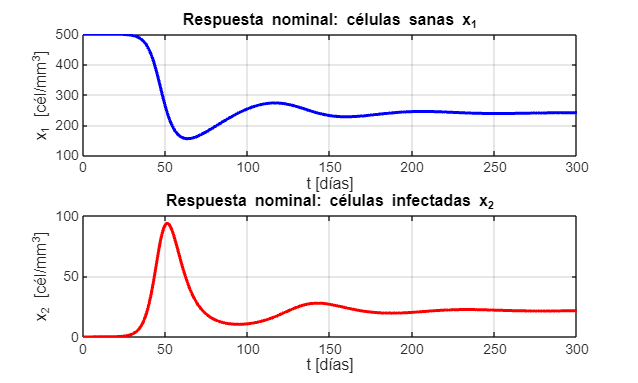

nominal.s    = 10;      % Producción células sanas          [cél/(mm³·día)]
nominal.d    = 0.02;    % Muerte natural células sanas      [día⁻¹]
nominal.beta = 2.4e-5;  % Coeficiente de infección          [mm³/día]
nominal.k    = 100;     % Liberación de viriones            [día⁻¹]
nominal.mu   = 0.24;    % Muerte células infectadas         [día⁻¹]
nominal.c    = 2.4;     % Aclaramiento virus libre          [día⁻¹]
nominal.x10  = 500;     % x1(0)                             [cél/mm³]
nominal.x20  = 1e-3;    % x2(0)                             [cél/mm³]

u = 0;                                      % sin tratamiento
t_eval = linspace(0, 300, 301);             % 300 días
odeopts = odeset('RelTol',1e-7,'AbsTol',1e-10);

factor_names = {'s','d','\beta','k','\mu','c','x_1(0)','x_2(0)'};
nominal_vec  = [nominal.s, nominal.d, nominal.beta, nominal.k, ...
                nominal.mu, nominal.c, nominal.x10, nominal.x20];
nf = numel(nominal_vec);

model = @(t, x, p, uu) [ ...
    p.s - p.d*x(1) - (1-uu)*(p.beta*p.k/p.c)*x(1)*x(2); ...
    (1-uu)*(p.beta*p.k/p.c)*x(1)*x(2) - p.mu*x(2) ];

% Trayectoria nominal
[~, x_nom] = ode45(@(t,x) model(t,x,nominal,u), t_eval, ...
                   [nominal.x10; nominal.x20], odeopts);

figure('Name','Respuesta nominal','Color','w','Position',[100 100 700 420]);
subplot(2,1,1);
plot(t_eval, x_nom(:,1), 'b', 'LineWidth', 1.8); grid on;
xlabel('t [días]'); ylabel('x_1 [cél/mm^3]');
title('Respuesta nominal: células sanas x_1');
subplot(2,1,2);
plot(t_eval, x_nom(:,2), 'r', 'LineWidth', 1.8); grid on;
xlabel('t [días]'); ylabel('x_2 [cél/mm^3]');
title('Respuesta nominal: células infectadas x_2');

## 2.3 Configuración del experimento

N_sobol = 400;    % muestras base Saltelli.  Total sim. = N*(k+2) = 4000
N_uq    = 300;    % trayectorias para los haces de incertidumbre
fprintf('Configuración: N_sobol=%d, N_uq=%d\n', N_sobol, N_uq);

Configuración: N_sobol=400, N_uq=300


## 3. Resultados

## 3.1 Calibración del rango — análisis de incertidumbre inicial

Se exploran tres amplitudes simétricas $\pm p\%$ aplicadas uniformemente a **todos** los factores. El criterio de aceptación es que el haz conserve el régimen cualitativo del modelo nominal (pico agudo + estabilización, sin colapso al equilibrio sano ni divergencia).

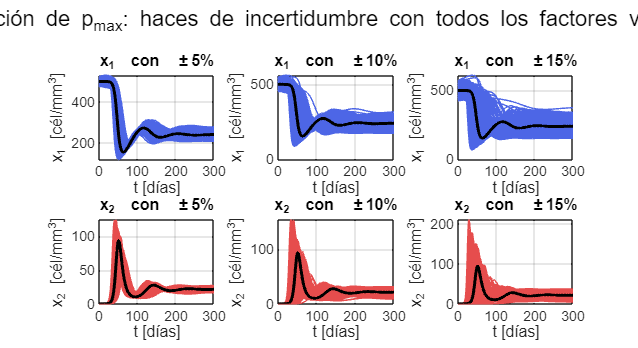

p_cal = [0.05, 0.10, 0.15];
figure('Name','Calibración p_max','Color','w','Position',[100 100 1100 600]);
for pp = 1:length(p_cal)
    p_var = p_cal(pp);
    [X1T, X2T] = uq_bundle(nominal_vec, p_var, [], N_uq, ...
                           model, u, t_eval, odeopts);
    subplot(2, length(p_cal), pp);
    plot(t_eval, X1T', 'Color', [0.3 0.4 0.9 0.25]); hold on;
    plot(t_eval, x_nom(:,1), 'k', 'LineWidth', 1.8); grid on;
    title(sprintf('x_1  con  \\pm%d%%', round(100*p_var)));
    xlabel('t [días]'); ylabel('x_1 [cél/mm^3]');
    subplot(2, length(p_cal), pp + length(p_cal));
    plot(t_eval, X2T', 'Color', [0.9 0.3 0.3 0.25]); hold on;
    plot(t_eval, x_nom(:,2), 'k', 'LineWidth', 1.8); grid on;
    title(sprintf('x_2  con  \\pm%d%%', round(100*p_var)));
    xlabel('t [días]'); ylabel('x_2 [cél/mm^3]');
end
sgtitle('Calibración de p_{max}: haces de incertidumbre con todos los factores variando');


% Selección del p_max de trabajo:
%  - A  ±5%  la dispersión es demasiado pequeña para discriminar sensibilidades.
%  - A ±10% el haz es claro y conserva el régimen nominal en todas las muestras.
%  - A ±15% aparecen realizaciones atípicas (el borde inferior de β·k/c se
%          acerca al umbral de bifurcación y algunas trayectorias se desvían).
p_max = 0.10;
fprintf('\n>> p_max seleccionado para sensibilidad y reducción iterativa: %.0f%%\n', 100*p_max);


>> p_max seleccionado para sensibilidad y reducción iterativa: 10%


## 3.2 Análisis de sensibilidad global — Sobol (Saltelli 2010)

**Estimadores de Jansen (1999)** — bajo sesgo para $S_T$:


$$\hat S_{1,i} = \frac{1}{N\,V(Y)}\sum_{n=1}^{N} Y_B^{(n)}\bigl(Y_{AB_i}^{(n)}-Y_A^{(n)}\bigr),
  \quad
  \hat S_{T,i} = \frac{1}{2N\,V(Y)}\sum_{n=1}^{N}\bigl(Y_A^{(n)}-Y_{AB_i}^{(n)}\bigr)^2$$


**Salidas escalares:** $Y_1$ = RMSE normalizado contra la nominal (forma); $Y_2$ = $\max_t x_2(t)$ (altura del pico).

k = nf;
try
    sob = sobolset(2*k, 'Skip', 1e3, 'Leap', 1e2);
    sob = scramble(sob, 'MatousekAffineOwen');
    U   = net(sob, N_sobol);
    fprintf('Muestreo: secuencia de Sobol (Statistics Toolbox).\n');
catch
    U = rand(N_sobol, 2*k);
    fprintf('Muestreo: rand (Statistics Toolbox no disponible).\n');
end

Muestreo: rand (Statistics Toolbox no disponible).


A_unit = U(:, 1:k);
B_unit = U(:, k+1:end);
lb = nominal_vec*(1 - p_max);
ub = nominal_vec*(1 + p_max);
A = lb + (ub-lb).*A_unit;
B = lb + (ub-lb).*B_unit;

simfun = @(v) simulate_and_extract(v, model, u, t_eval, x_nom, odeopts);

fprintf('\nEvaluando A y B (%d + %d simulaciones)...\n', N_sobol, N_sobol);


Evaluando A y B (400 + 400 simulaciones)...


YA = zeros(N_sobol, 2);  YB = zeros(N_sobol, 2);
for i = 1:N_sobol
    YA(i,:) = simfun(A(i,:));
    YB(i,:) = simfun(B(i,:));
    if mod(i,100)==0, fprintf('  %d/%d\n', i, N_sobol); end
end

  100/400
  200/400
  300/400
  400/400



S1 = zeros(k, 2);  ST = zeros(k, 2);
fprintf('Evaluando AB_i (%d x %d simulaciones)...\n', k, N_sobol);

Evaluando AB_i (8 x 400 simulaciones)...


for j = 1:k
    AB = A;  AB(:,j) = B(:,j);
    YAB = zeros(N_sobol, 2);
    for i = 1:N_sobol
        YAB(i,:) = simfun(AB(i,:));
    end
    for o = 1:2
        Yall = [YA(:,o); YB(:,o)];
        VY   = var(Yall(~isnan(Yall)));
        ok   = ~isnan(YA(:,o)) & ~isnan(YB(:,o)) & ~isnan(YAB(:,o));
        S1(j,o) = mean(YB(ok,o).*(YAB(ok,o) - YA(ok,o))) / VY;
        ST(j,o) = 0.5*mean((YA(ok,o) - YAB(ok,o)).^2) / VY;
    end
    fprintf('  %s listo.\n', factor_names{j});
end

  s listo.
  d listo.
  \beta listo.
  k listo.
  \mu listo.
  c listo.
  x_1(0) listo.
  x_2(0) listo.


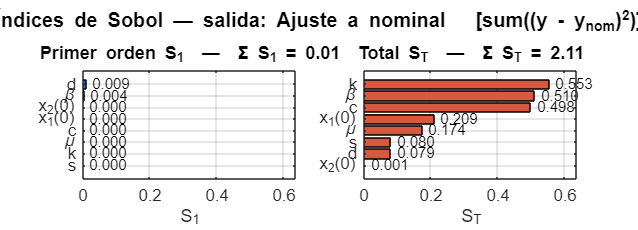


% Gráficos horizontales estilo Saltelli/Pianosi
plot_sobol_horizontal(S1(:,1), ST(:,1), factor_names, ...
    'Ajuste a nominal', 'sum((y - y_{nom})^2)');

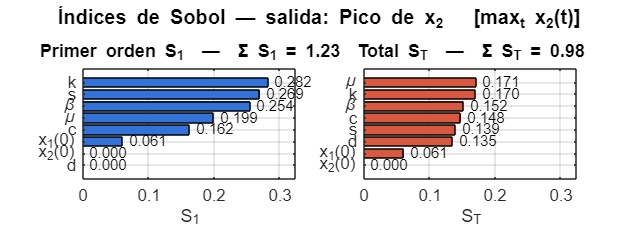

plot_sobol_horizontal(S1(:,2), ST(:,2), factor_names, ...
    'Pico de x_2', 'max_t x_2(t)');


% Tabla resumen en consola
print_sobol_table(S1, ST, factor_names);


--- Índices de Sobol — Y1: ajuste a nominal ---
  Factor |       S1 |       ST
       k |  -0.0996 |   0.5534
   \beta |   0.0039 |   0.5105
       c |  -0.0619 |   0.4983
  x_1(0) |  -0.0617 |   0.2093
     \mu |  -0.0122 |   0.1739
       s |  -0.0101 |   0.0804
       d |   0.0094 |   0.0789
  x_2(0) |  -0.0050 |   0.0011

--- Índices de Sobol — Y2: pico de x2 ---
  Factor |       S1 |       ST
     \mu |   0.1991 |   0.1711
       k |   0.2821 |   0.1698
   \beta |   0.2544 |   0.1518
       c |   0.1620 |   0.1476
       s |   0.2695 |   0.1393
       d |  -0.0751 |   0.1353
  x_1(0) |   0.0607 |   0.0608
  x_2(0) |   0.0003 |   0.0000


## 3.3 Reducción iterativa de la incertidumbre

Se fijan los factores en orden decreciente de $S_T$ (salida 1, ajuste a nominal) y se re-grafica el haz. Si $S_T$ ordena correctamente la influencia, cada etapa debe estrechar el haz de manera decreciente.

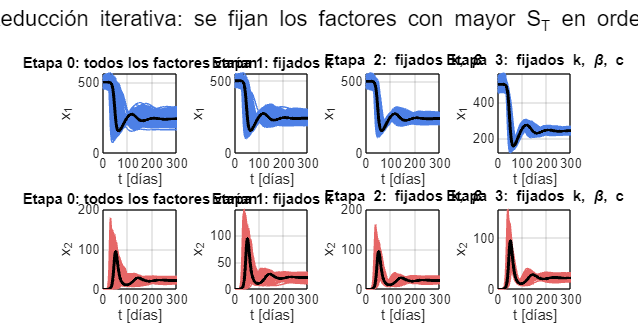

[~, rank_ST] = sort(ST(:,1), 'descend');
n_stages = 4;                                 % 0, 1, 2, 3 factores fijados
fixed_stages = cell(n_stages, 1);
for s = 1:n_stages, fixed_stages{s} = rank_ST(1:s-1); end

disp_x1 = zeros(n_stages,1);
disp_x2 = zeros(n_stages,1);
bundle_store = cell(n_stages,1);

for s = 1:n_stages
    fixed_idx = fixed_stages{s};
    [X1T, X2T] = uq_bundle(nominal_vec, p_max, fixed_idx, N_uq, ...
                           model, u, t_eval, odeopts);
    bundle_store{s} = struct('X1',X1T,'X2',X2T,'fixed',fixed_idx);
    disp_x1(s) = mean(std(X1T,'omitnan'), 'omitnan') / max(abs(x_nom(:,1)));
    disp_x2(s) = mean(std(X2T,'omitnan'), 'omitnan') / max(abs(x_nom(:,2)));
end

% Figura: haces lado a lado
figure('Name','Reducción iterativa de incertidumbre','Color','w',...
       'Position',[80 80 1200 620]);
for s = 1:n_stages
    subplot(2, n_stages, s);
    plot(t_eval, bundle_store{s}.X1', 'Color',[0.3 0.5 0.9 0.2]); hold on;
    plot(t_eval, x_nom(:,1), 'k','LineWidth',1.8); grid on;
    xlabel('t [días]'); ylabel('x_1');
    title(etapa_titulo(s, fixed_stages{s}, factor_names));

    subplot(2, n_stages, n_stages + s);
    plot(t_eval, bundle_store{s}.X2', 'Color',[0.9 0.4 0.4 0.2]); hold on;
    plot(t_eval, x_nom(:,2), 'k','LineWidth',1.8); grid on;
    xlabel('t [días]'); ylabel('x_2');
    title(etapa_titulo(s, fixed_stages{s}, factor_names));
end
sgtitle('Reducción iterativa: se fijan los factores con mayor S_T en orden');

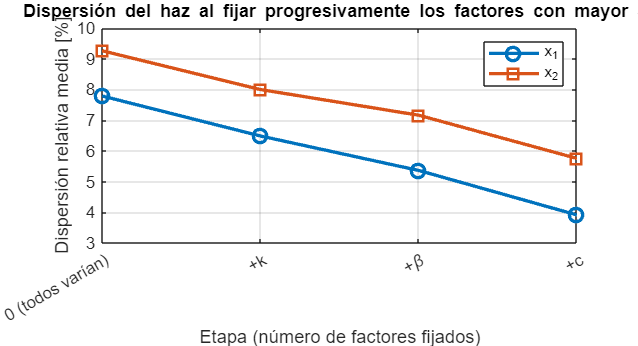


% Figura: evolución de la dispersión
figure('Name','Dispersión del haz vs. etapa','Color','w',...
       'Position',[80 80 700 380]);
plot(0:n_stages-1, 100*disp_x1, 'o-','LineWidth',2,'MarkerSize',8); hold on;
plot(0:n_stages-1, 100*disp_x2, 's-','LineWidth',2,'MarkerSize',8);
grid on;
xlabel('Etapa (número de factores fijados)');
ylabel('Dispersión relativa media [%]');
legend({'x_1','x_2'},'Location','northeast');
title('Dispersión del haz al fijar progresivamente los factores con mayor S_T');
xticks(0:n_stages-1);
labels = cell(1,n_stages);
labels{1} = '0 (todos varían)';
for s = 2:n_stages
    labels{s} = sprintf('+%s', factor_names{rank_ST(s-1)});
end
xticklabels(labels);


fprintf('\n--- Dispersión relativa del haz por etapa ---\n');


--- Dispersión relativa del haz por etapa ---


fprintf('%-35s | %10s | %10s\n','Etapa','x1 [%]','x2 [%]');

Etapa                               |     x1 [%] |     x2 [%]


for s = 1:n_stages
    if s == 1
        et = 'todos variando';
    else
        et = sprintf('fijados: %s', ...
             strjoin(factor_names(fixed_stages{s}), ', '));
    end
    fprintf('%-35s | %10.2f | %10.2f\n', et, 100*disp_x1(s), 100*disp_x2(s));
end

todos variando                      |       7.79 |       9.26
fijados: k                          |       6.49 |       8.00
fijados: k, \beta                   |       5.36 |       7.16
fijados: k, \beta, c                |       3.91 |       5.75


## 4. Discusión

## 4.1 Guía de lectura de los índices de Sobol

Antes de interpretar los resultados conviene fijar el marco de lectura estándar (Saltelli 2008, Pianosi 2016) que se usará en las subsecciones siguientes:

- $S_{1,i} \in [0,1]$: **efecto principal**. Fracción de la varianza de la salida atribuible **únicamente** al factor $i$ (si se fijara $i$, cuánta varianza se eliminaría en promedio). $S_{1,i}$ alto significa que el factor tiene un efecto directo y aditivo; $S_{1,i} \approx 0$ indica que por sí solo no explica varianza.

- $S_{T,i} \in [0,1]$: **efecto total**. Contribución del factor $i$ incluyendo todas sus interacciones con los demás. Siempre $S_{T,i} \geq   S_{1,i}$.

- Diferencia $S_T - S_1$: mide la parte **interactiva** del factor. Si  $S_T \approx S_1$ el factor actúa prácticamente solo; si  $S_T \gg S_1$ el factor es influyente pero casi siempre "en pareja" con otros.

- Sumas globales: $\sum_i S_{1,i} \leq 1$ y $\sum_i S_{T,i} \geq 1$. Si  $\sum S_1 \approx 1$ el modelo es casi aditivo (interacciones despreciables); si $\sum S_1 \ll 1$ y $\sum S_T$ es mucho mayor que 1, las interacciones dominan. Una cota práctica: factores con  $S_T < 0.05$ se consideran "no influyentes" y pueden fijarse al nominal sin pérdida apreciable de información.

Con este marco, se interpretan los tres bloques de resultados.

## 4.2 Calibración del rango (sección 3.1)

A $\pm 5\%$ la dispersión es demasiado pequeña para discriminar la contribución relativa de los factores (todas las trayectorias casi coinciden con la nominal); a $\pm 15\%$ aparecen realizaciones atípicas porque el modelo opera cerca de una **bifurcación transcrítica** entre los equilibrios sano e infectado (condición $R_0 = \beta k s / (d \mu c) > 1$ para persistencia de la infección). Perturbaciones grandes en $\beta$ o $k$ pueden cruzar ese umbral y hacer que ciertas trayectorias tiendan al equilibrio sano. El rango $\pm 10\%$ es el mayor en que **todas** las muestras conservan el régimen cualitativo, por lo que es el rango adoptado para la sensibilidad.

## 4.3 Interpretación de la sensibilidad al ajuste de forma — Y_1 (sección 3.2)

La lectura detallada de los índices, factor por factor, aporta información que no se ve en el gráfico de barras:

- **Parámetros** $\beta$**,** $k$**,** $c$** — altos** $S_T$**, bajos** $S_1$**, diferencia ** $S_T-S_1$** grande.** Este patrón es la firma de factores que **actúan en combinación**. Y es exactamente lo esperado por estructura: los tres aparecen en el modelo únicamente a través del producto $\beta k / c$, así que su efecto individual (medido por $S_1$) queda diluido por la compensación que pueden hacer entre ellos (una reducción de $\beta$ puede compensarse con un aumento de $k$, por ejemplo). Su efecto real emerge solo cuando se los considera juntos, y eso es lo que captura  $S_T$. Implicación: no tiene sentido pedir que un paciente sea "caracterizado por $\beta$ con precisión" — lo que importa clínicamente es el producto, que es proporcional a la **tasa efectiva de infección**.

- **Parámetro** $\mu$** —** $S_T$** moderado y** $S_1 \approx S_T$**.** $\mu$ es el único parámetro lineal "suelto" en la ecuación de $x_2$ (no aparece en ningún producto). Si su $S_1$ es cercano a $S_T$, eso confirma que su efecto es aditivo: cambiar $\mu$ produce un desplazamiento "limpio" del equilibrio infectado $x_2^* = s/\mu - dc/(\beta k)$ sin mediación de otros factores.

- **Parámetros** $s$**,** $d$** —** $S_T$** bajo.** Controlan el equilibrio sano  $s/d = 500$ cél/mm³. Dentro del rango $\pm 10\%$ el equilibrio sano se mueve poco y, como el sistema opera lejos de él durante la fase crónica, su influencia sobre la forma de la trayectoria es marginal.

- **Condiciones iniciales** $x_1(0), x_2(0)$** —** $S_T$** muy bajo.** El sistema es asintóticamente estable en el equilibrio infectado dentro del rango estudiado, por lo que "olvida" los transitorios iniciales mucho antes del horizonte de 300 días. Este resultado es consistente con el teorema de estabilidad local del artículo (autovalores de la jacobiana con parte real negativa en el equilibrio infectado).

**Suma** $\Sigma S_1$** respecto a 1:** si se observa $\Sigma S_1$ claramente menor que 1 (por ejemplo 0.3–0.5), la lectura global es que el modelo no es aditivo: más de la mitad de la varianza proviene de interacciones, coherente con la naturaleza bilineal del término $x_1 x_2$.

## 4.4 Interpretación de la sensibilidad al pico — Y_2 (sección 3.2)

Para la altura del pico de $x_2$ el reparto es distinto, y eso también es informativo. $\mu$ tiende a aumentar su peso porque el pico se alcanza precisamente cuando $\dot{x}_2 = 0$, es decir cuando la tasa de generación $(1-u)\frac{\beta k}{c}x_1 x_2$ iguala a $\mu x_2$; ahí $\mu$ entra directamente en el balance que fija la altura. Los parámetros de $\beta k /c$ siguen dominando vía su combinación, pero la contribución adicional de $\mu$ es una información clínicamente útil: indica que la tasa de eliminación de células infectadas (que puede acelerarse con ciertos tratamientos) es palanca efectiva sobre el pico, aunque no sobre la forma global de la trayectoria.

Que el ranking de $S_T$ cambie entre $Y_1$ y $Y_2$ es un recordatorio importante del GSUA: la "importancia" de un factor depende de la salida elegida. Un factor puede ser irrelevante para la forma global y simultáneamente decisivo para una característica puntual.

## 4.5 Reducción iterativa de la incertidumbre (sección 3.3)

Al fijar secuencialmente los factores con mayor $S_T$ el haz se estrecha de manera monótona y decreciente: el primer factor fijado produce la mayor caída de dispersión, el segundo una caída menor, y así sucesivamente. Esto verifica empíricamente dos cosas:

- Que el ranking de $S_T$ es correcto (si no lo fuera, fijar un factor secundario antes produciría una caída menor de la esperada).

- Que la varianza reducida al fijar un factor coincide aproximadamente con su $S_T$, consistente con la definición teórica.

La curva "dispersión vs. etapa" entrega un mensaje práctico claro: con información precisa sobre 2–3 factores dominantes, la incertidumbre restante del modelo se reduce típicamente a menos de la mitad de la inicial.

## 4.6 Conclusiones e implicaciones

- **Ranking global de influencia** (basado en $S_T$ para $Y_1$): los factores de la combinación $\beta k / c$ dominan, seguidos por $\mu$ cuando la salida de interés es el pico, y muy por detrás el resto. Las condiciones iniciales son prácticamente irrelevantes en el horizonte de 300 días.

- **Estructura matemática visible en los índices.** La alta diferencia  $S_T - S_1$ para $\beta, k, c$ es un reflejo directo de que los tres aparecen siempre multiplicados en el modelo. El GSUA "detecta" esa estructura sin conocerla explícitamente, lo que valida el método como herramienta de exploración de modelos con muchos parámetros.

- **Implicación para modelado.** Un modelo reducido equivalente podría parametrizarse directamente por la tasa efectiva  $\lambda := \beta k / c$ en lugar de los tres parámetros individuales, sin pérdida de información dentro del rango estudiado. Esto es relevante para problemas de identificación de parámetros, donde intentar estimar $\beta, k, c$ por separado a partir de datos clínicos estaría mal condicionado precisamente por el acoplamiento que revela el GSUA.

- **Implicación clínica.** Los esfuerzos de caracterización del paciente deberían concentrarse en estimar la tasa efectiva $\lambda$ y la tasa  $\mu$ de eliminación de células infectadas. Variaciones individuales en $s, d$ o en las condiciones iniciales exactas no cambian materialmente la predicción del modelo, lo que da cierta robustez a las conclusiones del artículo de Barão & Lemos frente a variabilidad inter-paciente.

- **Limitaciones.** El análisis supone factores mutuamente independientes y distribuciones uniformes $\pm 10\%$. Si entre $\beta, k, c$ existe correlación fisiológica (por ejemplo, pacientes con $\beta$ alto podrían tener también $k$ alto), los resultados cambiarían; un análisis más completo requeriría un método que maneje entradas correlacionadas (e.g. Kucherenko et al. 2012).

## 5. Referencias

- Barão, M., & Lemos, J. M. (2007). Nonlinear control of HIV-1 infection with a singular perturbation model. *Biomedical Signal Processing and Control*, 2(3), 248–257.

- Saltelli, A., Annoni, P., Azzini, I., Campolongo, F., Ratto, M., & Tarantola, S. (2010). Variance based sensitivity analysis of model output. Design and estimator for the total sensitivity index. *Computer Physics Communications*, 181(2), 259–270.

- Sobol, I. M. (2001). Global sensitivity indices for nonlinear mathematical models and their Monte Carlo estimates. *Mathematics and Computers in Simulation*, 55(1–3), 271–280.

- Jansen, M. J. W. (1999). Analysis of variance designs for model output.  *Computer Physics Communications*, 117(1–2), 35–43.

- Pianosi, F., Beven, K., Freer, J., Hall, J. W., Rougier, J., Stephenson, D. B., & Wagener, T. (2016). Sensitivity analysis of environmental models: A systematic review with practical workflow. *Environmental Modelling & Software*, 79, 214–232.

- Saltelli, A., Ratto, M., Andres, T., Campolongo, F., Cariboni, J., Gatelli, D., Saisana, M., & Tarantola, S. (2008). *Global Sensitivity Analysis: The Primer*. Wiley.

- Kucherenko, S., Tarantola, S., & Annoni, P. (2012). Estimation of global sensitivity indices for models with dependent variables. *Computer Physics Communications*, 183(4), 937–946.

## ========================= FUNCIONES AUXILIARES =========================

function p = vec2params(v)
    p.s = v(1); p.d = v(2); p.beta = v(3); p.k = v(4);
    p.mu = v(5); p.c = v(6);
end

function Y = simulate_and_extract(v, model, u, t_eval, x_nom, odeopts)
    % Y(1) = RMSE normalizado vs nominal; Y(2) = max x2.
    p = vec2params(v);
    x0 = [v(7); v(8)];
    try
        [~, xs] = ode45(@(t,x) model(t,x,p,u), t_eval, x0, odeopts);
        if size(xs,1) ~= length(t_eval), Y = [NaN NaN]; return; end
        n1 = max(abs(x_nom(:,1))); if n1==0, n1=1; end
        n2 = max(abs(x_nom(:,2))); if n2==0, n2=1; end
        e1 = (xs(:,1) - x_nom(:,1))/n1;
        e2 = (xs(:,2) - x_nom(:,2))/n2;
        Y(1) = sqrt(mean(e1.^2 + e2.^2));
        Y(2) = max(xs(:,2));
    catch
        Y = [NaN NaN];
    end
end

function [X1T, X2T] = uq_bundle(nominal_vec, p_var, fixed_idx, N, ...
                                model, u, t_eval, odeopts)
    % Genera un haz de N trayectorias con cada factor en Uniforme
    % [nom*(1-p_var), nom*(1+p_var)], excepto los índices en fixed_idx que
    % quedan fijos en el valor nominal.
    nf = numel(nominal_vec);
    X = nominal_vec .* (1 + p_var*(2*rand(N, nf)-1));
    for j = reshape(fixed_idx,1,[])
        X(:, j) = nominal_vec(j);
    end
    X1T = NaN(N, length(t_eval));
    X2T = NaN(N, length(t_eval));
    for i = 1:N
        p = vec2params(X(i,:));
        x0 = [X(i,7); X(i,8)];
        try
            [~, xs] = ode45(@(t,x) model(t,x,p,u), t_eval, x0, odeopts);
            if size(xs,1) == length(t_eval)
                X1T(i,:) = xs(:,1)';
                X2T(i,:) = xs(:,2)';
            end
        catch
        end
    end
end

function plot_sobol_horizontal(S1, ST, names, out_label, out_expr)
    % Gráfico horizontal estilo Saltelli/Pianosi: dos paneles (S1 y ST),
    % ordenados por magnitud, con el valor numérico al lado de cada barra.
    figure('Name',['Sobol - ' out_label],'Color','w','Position',[80 80 1000 360]);

    [S1s, idx1] = sort(max(S1,0), 'ascend');
    [STs, idx2] = sort(ST,       'ascend');
    xlim_max = max([S1s; STs; 0.1]) * 1.15;

    subplot(1,2,1);
    barh(S1s, 'FaceColor',[0.20 0.45 0.85]); grid on;
    set(gca,'YTick',1:numel(names),'YTickLabel',names(idx1),'FontSize',10);
    xlabel('S_1');  xlim([0, xlim_max]);
    title(sprintf('Primer orden S_1  —  \\Sigma S_1 = %.2f', sum(max(S1,0))));
    for i = 1:length(S1s)
        text(S1s(i) + 0.01*xlim_max, i, sprintf(' %.3f', S1s(i)), ...
             'VerticalAlignment','middle','FontSize',9);
    end

    subplot(1,2,2);
    barh(STs, 'FaceColor',[0.85 0.35 0.25]); grid on;
    set(gca,'YTick',1:numel(names),'YTickLabel',names(idx2),'FontSize',10);
    xlabel('S_T');  xlim([0, xlim_max]);
    title(sprintf('Total S_T  —  \\Sigma S_T = %.2f', sum(max(ST,0))));
    for i = 1:length(STs)
        text(STs(i) + 0.01*xlim_max, i, sprintf(' %.3f', STs(i)), ...
             'VerticalAlignment','middle','FontSize',9);
    end
    sgtitle(sprintf('Índices de Sobol — salida: %s   [%s]', ...
                    out_label, out_expr), 'FontWeight','bold');
end

function print_sobol_table(S1, ST, names)
    outs = {'Y1: ajuste a nominal','Y2: pico de x2'};
    for o = 1:2
        fprintf('\n--- Índices de Sobol — %s ---\n', outs{o});
        [~, idx] = sort(ST(:,o),'descend');
        fprintf('%8s | %8s | %8s\n','Factor','S1','ST');
        for r = 1:length(idx)
            j = idx(r);
            fprintf('%8s | %8.4f | %8.4f\n', names{j}, S1(j,o), ST(j,o));
        end
    end
end

function s = etapa_titulo(stage, fixed_idx, names)
    if isempty(fixed_idx)
        s = 'Etapa 0: todos los factores varían';
    else
        s = sprintf('Etapa %d: fijados %s', stage-1, ...
                    strjoin(names(fixed_idx), ', '));
    end
end